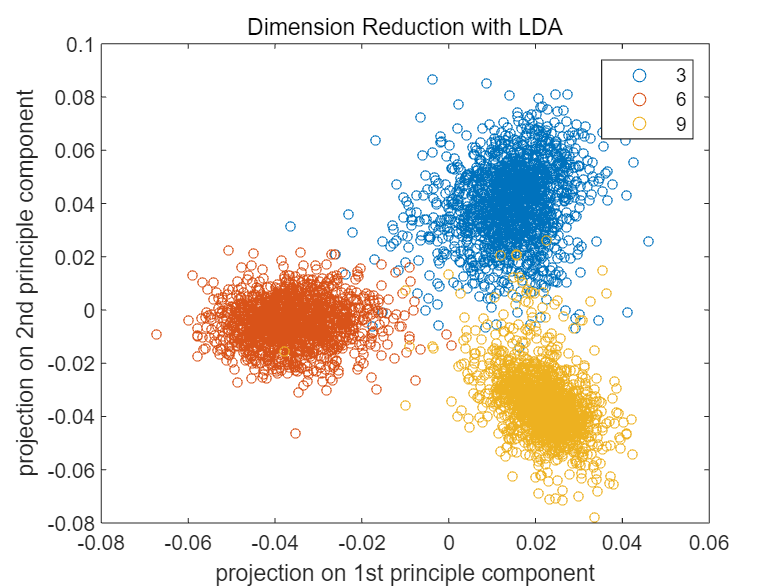

load mnist-3-6-9.mat %each column represent an sample(image)

%Normalize
digitNormalize=[digit3 digit6 digit9];
for i=1:size(digitNormalize,1)
    data=digitNormalize(i,:);
    [data,~]=mapminmax(data,0,1);
    digitNormalize(i,:)=data;
end

%compute mean of all classes
mean_all=mean(digitNormalize,2);
%compue mean of each class
mean_3=mean(digitNormalize(:,1:1500),2);
mean_6=mean(digitNormalize(:,1501:3000),2);
mean_9=mean(digitNormalize(:,3001:4500),2);

%compute between-class scatter
Mb=[mean_3-mean_all mean_6-mean_all mean_9-mean_all];
Sb=Mb*(Mb.');

%compute within-class scatter
Mw=[digitNormalize(:,1:1500)-mean_3 digitNormalize(:,1501:3000)-mean_6 digitNormalize(:,3001:4500)-mean_9];
Sw=Mw*(Mw.');

%solve eigenvalue problem
I=eye(size(Sw));
[eigenvectors,eigenvalues]=eigs(inv(Sw+0.0001*I)*Sb);

%find the first two principal component
eigenvaluesMax=max(abs(eigenvalues));
[principalValue_1,principalValueIndex_1]=max(eigenvaluesMax);
eigenvaluesMax(principalValueIndex_1)=0;
[principalValue_2,principalValueIndex_2]=max(eigenvaluesMax);
principalVector_1=eigenvectors(:,principalValueIndex_1);
principalVector_2=eigenvectors(:,principalValueIndex_2);

%compute the projection to the first two principal component
E=repmat(mean_all,1,size(digitNormalize,2));
digitNormalize=digitNormalize-E;
projection_1=principalVector_1.'*digitNormalize;
projection_2=principalVector_2.'*digitNormalize;

%plot
figure(1)
colormap("summer")
scatter(projection_1(:,1:1500),projection_2(:,1:1500),20,'o');hold on
scatter(projection_1(:,1501:3000),projection_2(:,1501:3000),20,'o');hold on
scatter(projection_1(:,3000:4500),projection_2(:,3000:4500),20,'o');hold off
box on
legend('3','6','9');
xlabel('projection on 1st principle component');
ylabel('projection on 2nd principle component');
title('Dimension Reduction with LDA')

save data_LDA projection_1 projection_2